# Fokker-Planck equation solve

[Problem in solving a Fokker-Planck equation - MATLAB Answers - MATLAB Central](https://ww2.mathworks.cn/matlabcentral/answers/1998963-problem-in-solving-a-fokker-planck-equation)

clear;
% define grids 
Nx = 100; Ny = 100; Nt = 1000;
xmin = 0; xmax = 3;
ymin = 0; ymax = 3;

x = linspace(xmin, xmax, Nx);
y = linspace(ymin, ymax, Ny);
dx = x(2) - x(1);
dy = y(2) - y(1);
tmin = 0; tmax = 1;
dt = (tmax - tmin) / (Nt - 1);
D = 0.04;


%parameter values
a = 1; b = 1; S = 0.5; k1 = 1; k2 = 1; n = 4;

F1 =@(x,y) (a*x.^n)./(S^n+x.^n)+(b*S^n)./(S^n+y.^n)-k1*x;
F2 =@(x,y) (a*y.^n)./(S^n+y.^n)+(b*S^n)./(S^n+x.^n)-k1*y;
P = zeros(Nx,Ny,Nt);
Pk = zeros(Nx, Ny);
%Initial conditions
[X, Y] = meshgrid(x,y);
X = X'; Y = Y';          % Now X, Y are Nx-by-Ny
P(:,:,1) = exp(-((X-0.1).^2 + (Y).^2)/2);

%% Boundary conditions
P(1, :, :) = 0; P(Nx, :, :) = 0;
P(:, 1, :) = 0; P(:, Ny, :) = 0;

F1_grid = F1(X, Y);      % Nx-by-Ny
F2_grid = F2(X, Y);      % Nx-by-Ny
tic;
for k = 1:Nt-1
    % 取出当前时刻的P
    Pk = P(:,:,k);

    % 计算中心差分（仅对内部点）
    P_ip1 = Pk(3:Nx, 2:Ny-1);
    P_im1 = Pk(1:Nx-2, 2:Ny-1);
    P_jp1 = Pk(2:Nx-1, 3:Ny);
    P_jm1 = Pk(2:Nx-1, 1:Ny-2);
    P_center = Pk(2:Nx-1, 2:Ny-1);

    F1_center = F1_grid(2:Nx-1, 2:Ny-1);
    F1_ip1 = F1_grid(3:Nx, 2:Ny-1);
    F1_im1 = F1_grid(1:Nx-2, 2:Ny-1);

    F2_center = F2_grid(2:Nx-1, 2:Ny-1);
    F2_jp1 = F2_grid(2:Nx-1, 3:Ny);
    F2_jm1 = F2_grid(2:Nx-1, 1:Ny-2);

    term1 = -P_center .* ((F1_ip1 - F1_im1) / (2*dx));
    term2 = -P_center .* ((F2_jp1 - F2_jm1) / (2*dy));
    term3 = -F1_center .* ((P_ip1 - P_im1) / (2*dx));
    term4 = -F2_center .* ((P_jp1 - P_jm1) / (2*dy));
    term5 = D * ( ...
        (P_ip1 - 2*P_center + P_im1) / dx^2 + ...
        (P_jp1 - 2*P_center + P_jm1) / dy^2 ...
    );

    P(2:Nx-1, 2:Ny-1, k+1) = P_center + dt * (term1 + term2 + term3 + term4 + term5);

    % 边界条件
    P(1,:,k+1) = 0; P(Nx,:,k+1) = 0;
    P(:,1,k+1) = 0; P(:,Ny,k+1) = 0;
end
toc;

历时 0.161189 秒。


PNt_2 = P(:,:,Nt);
m = max(PNt_2(:))

m = 1.2427

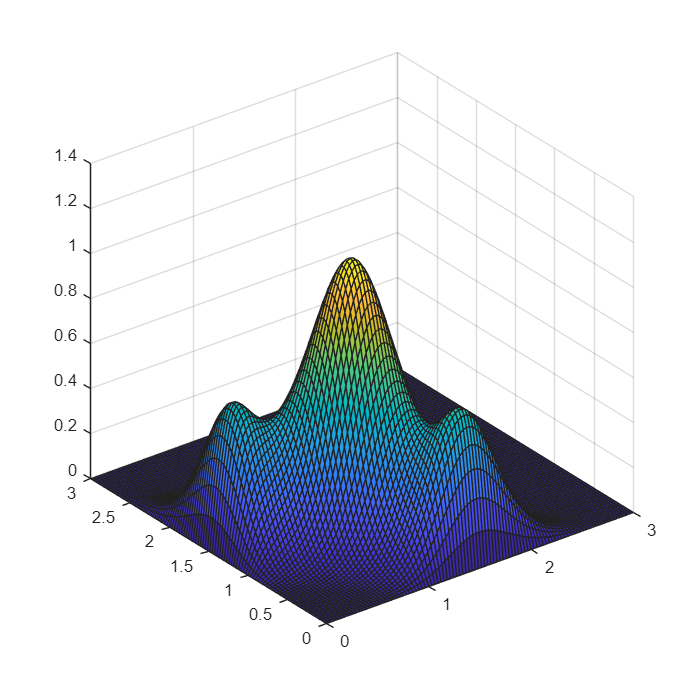

figure
surf(x, y, PNt_2');